classes = 2×1 categorical array
     AD 
     NC 


Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 2 workers.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       50.00% |       50.00% |       0.8544 |       0.7605 |          0.0100 |
|       1 |          30 |       00:00:56 |       82.81% |      100.00% |       0.4363 |       0.1624 |          0.0100 |
|       2 |          50 |       00:01:32 |       84.38% |              |       0.3154 |              |          0.0100 |
|   

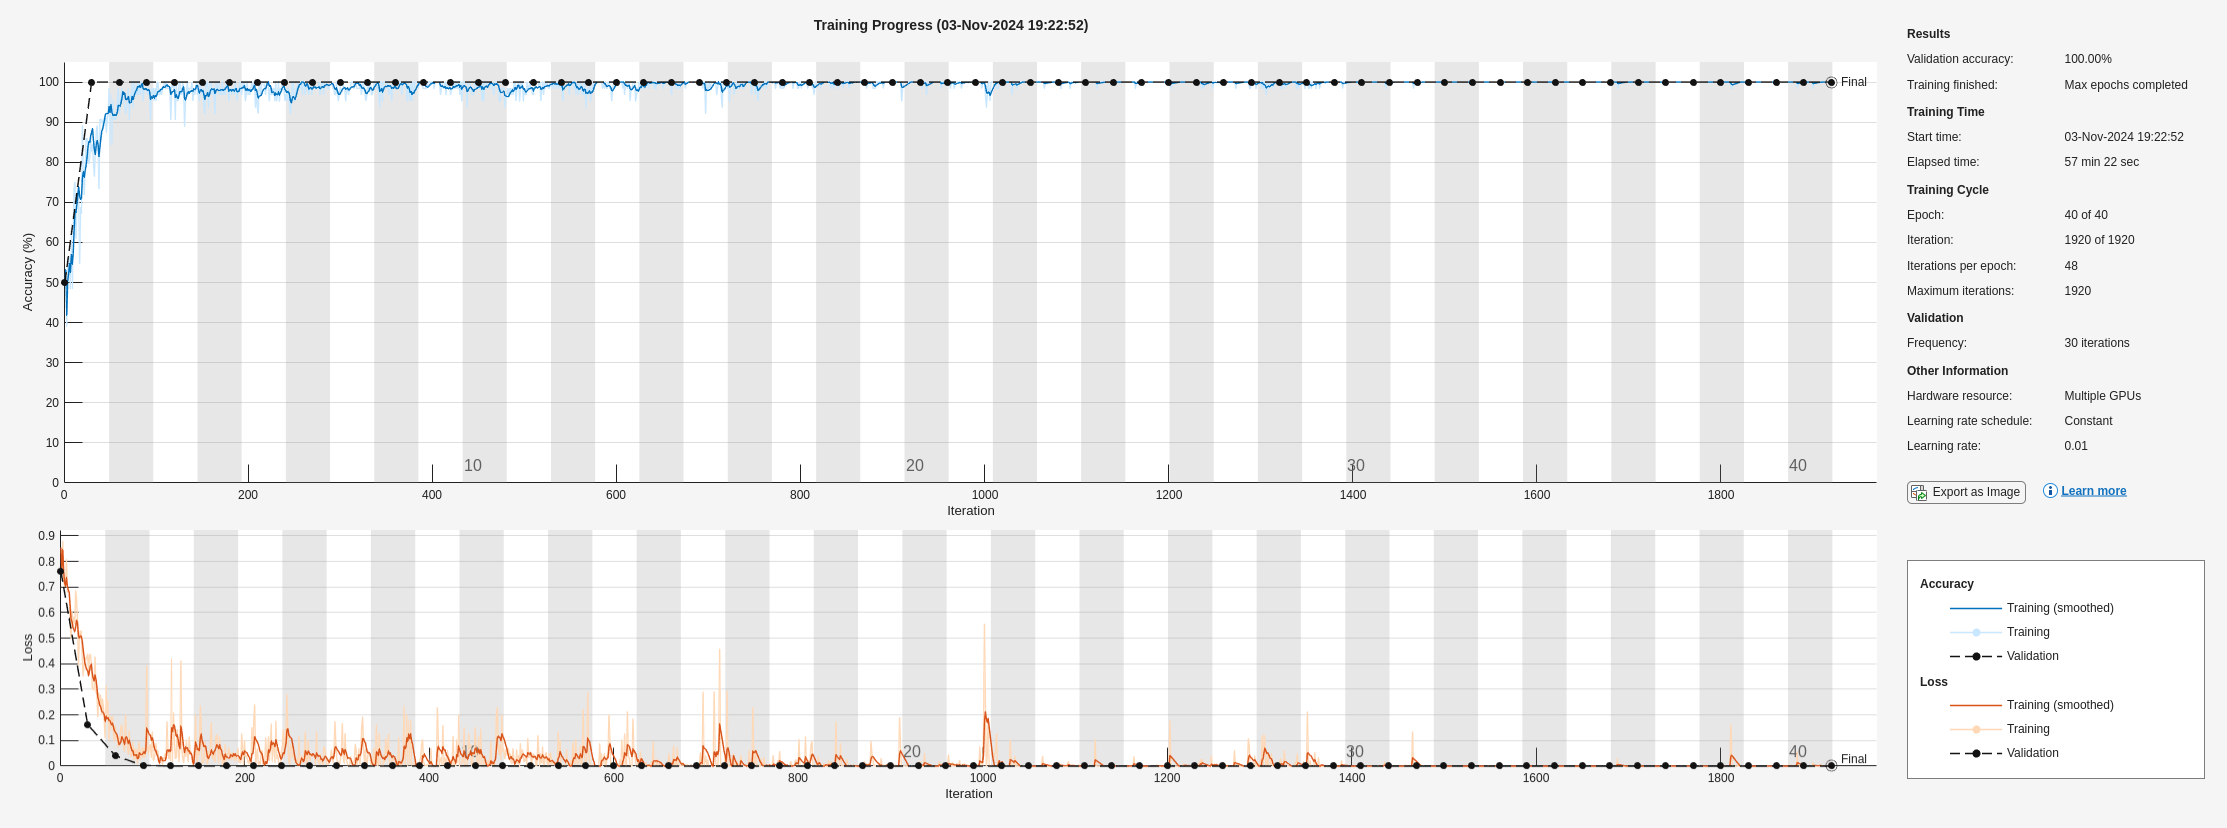

clear
clc

VONNPath = pwd;
CS670Path = fullfile(VONNPath, "Patrick Do/CS670");


testDataOpt = "AVOData_Psy_80Train_20Test_V1R3S_Test_1PerClass";
testDataFolder = fullfile(CS670Path, "Data_CS670", testDataOpt);
imdsVal = imageDatastore(testDataFolder, ...
            "IncludeSubfolders",true, "LabelSource", "foldernames", ...
            "FileExtensions", ".mat", "ReadFcn",@loadPD);

for k=11:11
    for dataOpt = ["AVOData_Psy_80Train_20Test_V1R3S_Train_50PerClass"]
        dataFolder = fullfile(CS670Path, "Data_CS670", dataOpt);
        imdsTrain = imageDatastore(dataFolder, ...
                "IncludeSubfolders",true, "LabelSource", "foldernames", ...
                "FileExtensions", ".mat", "ReadFcn",@loadPD);
        
        augmentedDataFolder = fullfile(CS670Path, "Augmented_Data_V1_CS670", dataOpt);
        
        % Load and combined augmented data
        combinedTrainFiles = [imdsTrain.Files];
        combinedTrainLabels = [imdsTrain.Labels];
        for importanceThres = 0.5:0.25:1
            for weight = 0.1:0.1:1
                % Load all train data
                enhancedImageTrainFolder = fullfile(augmentedDataFolder, ...
                    strcat("weight_", num2str(weight), "_importanceThres_", num2str(importanceThres)), "Train");
                enhancedImageTrainImds = imageDatastore(enhancedImageTrainFolder, "IncludeSubfolders", true, ...
                    "LabelSource","foldernames","FileExtensions",".mat", "ReadFcn", @loadEnhancedImage);
                combinedTrainFiles = [combinedTrainFiles; enhancedImageTrainImds.Files];
                combinedTrainLabels = [combinedTrainLabels; enhancedImageTrainImds.Labels];
            end
        end
        
        imdsTrain = imageDatastore(combinedTrainFiles, "Labels", categorical(combinedTrainLabels), ...
            "ReadFcn", @loadEnhancedImage, "FileExtensions", ".mat");
        
        classes = unique(imdsTrain.Labels)
        inputSize = [91 109 91 1];
        outputSize = length(classes);
        dropRate = 0.2;
        classWeights =  [1 1];
        layers = resnet101_3DTNV_Retrained(inputSize, outputSize, dropRate, classes, classWeights);

        curDate = "Oct30";
        savePath = fullfile(CS670Path, "Results_CS670", dataOpt);
        if ~exist(savePath, "dir")
            mkdir(savePath);
        end
        filename = strcat("resnet101Retrained_SAAugmentationV1_", curDate, "_trial_", num2str(k));

        maxEpoch = 40;
        options = trainingOptions('sgdm', ...
            'ExecutionEnvironment','multi-gpu',...
            'InitialLearnRate',0.01, ...
            'L2Regularization',0.0005,...
            'GradientThreshold',0.05, ...
            'MaxEpochs',maxEpoch, ...
            'Shuffle','every-epoch', ...
            'ValidationData',imdsVal, ...
            'ValidationFrequency',30, ...
            'Verbose',true,...
            'MiniBatchSize',64,...
            'ValidationPatience',Inf,...
            'OutputNetwork','last-iteration',...
            'Plots','training-progress');
        
        net = trainNetwork(imdsTrain, layers, options);
       save(fullfile(savePath, strcat(filename, ".mat")), "net", "options")
    end
end